# Spatiotemporal Data Analysis

## Adapted from read_data.m, generated form Kundu et. al, written by Dr. Tamas Jozsa

%This file is made in .mlx to create faster debugging

clear all
close all
clc

### READ CHANNEL PARAMETERS AND SPATIO-TEMPORAL AVERAGES

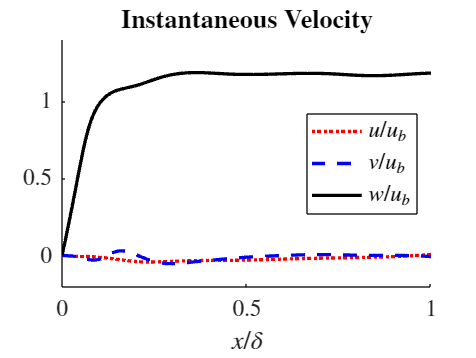

% read parameters
% Lz, Lx, Ly, nu, Delta p
params = xlsread('Reynolds_stresses.xlsx','parameters');

Lz = params(1); Lx = params(2); Ly = params(3);
nu = params(4); % kinematic viscosity

% these values are equal to unity because they are the reference quantities
% used to make the data dimensionless
u_b = 1.0; % bulk velocity (average velocity in the entire channel)
rho = 1.0; % density
delta = Lx/2; % boundary layer thickness  =  channel half-height

% bulk Reynolds number based on channel half height and mean velocity
Re_b  =  u_b*delta/nu;

% read wall-normal coordinate and spatio-temporal averages
% x, <w>, <w'w'>, <u'u'> , <v'v'>, <u'w'>
ST_ave_dat = xlsread('Reynolds_stresses.xlsx','Reynolds_stresses');


%% READ TIME SAMPLES AT PROBES PLACED ALONG A WALL_NORMAL LINE

hinfo  =  hdf5info('time_samples.hdf5');

% sampling time
t_smpl = hdf5read(hinfo.GroupHierarchy.Datasets(1));
% wall-normal location of the samples
x_smpl = hdf5read(hinfo.GroupHierarchy.Datasets(5))+1.0;

% sampled velocity components
% each row represents a time instant as dictated by t_smpl
% each column represents a spatial location as dictated by y_smpl
w_smpl = hdf5read(hinfo.GroupHierarchy.Datasets(2));
u_smpl = hdf5read(hinfo.GroupHierarchy.Datasets(3));
v_smpl = hdf5read(hinfo.GroupHierarchy.Datasets(4));


%% instantaneous velocity plots
figure(1)
title('$\textbf{Instantaneous Velocity}$','Interpreter','latex','FontSize',14)
hold on
plot(x_smpl,u_smpl(1,:),':r',LineWidth=2)
plot(x_smpl,v_smpl(1,:),'--b',LineWidth=2)
plot(x_smpl,w_smpl(1,:),'-k',LineWidth=2)
xlabel('$x/\delta$','Interpreter','latex','FontSize',14)
xlim([0,1])
ylim([-0.2,1.4])
legend('$u/u_b$','$v/u_b$','$w/u_b$',...
    'Interpreter','latex','FontSize',14,'Location','east')
set(gca,'TickLabelInterpreter','latex','FontSize',14)
hold off

### Mean and Standard Deviation at Every Sampling Point

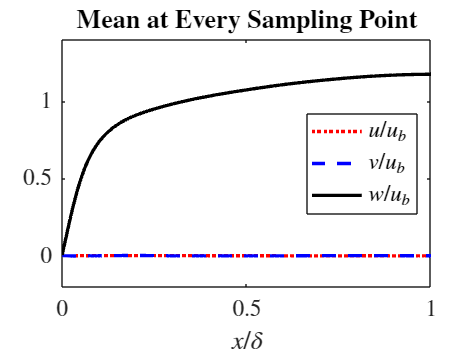

%u-velocity sampling
u_means = mean(u_smpl, 1);
u_stds = std(u_smpl, 0, 1);

%v-velocity sampling
v_means = mean(v_smpl, 1);
v_stds = std(v_smpl, 0, 1);

%w-velocity sampling
w_means = mean(w_smpl, 1);
w_stds = std(w_smpl, 0, 1);

%Plotting the Mean and STD
figure(2)
plot(x_smpl,u_means,':r',LineWidth=2)
hold on
plot(x_smpl,v_means,'--b',LineWidth=2)
plot(x_smpl,w_means,'-k',LineWidth=2)
title('$\textbf{Mean at Every Sampling Point}$','Interpreter','latex','FontSize',14)
xlabel('$x/\delta$','Interpreter','latex','FontSize',14)
xlim([0,1])
ylim([-0.2,1.4])
legend('$u/u_b$','$v/u_b$','$w/u_b$',...
    'Interpreter','latex','FontSize',14,'Location','east')
set(gca,'TickLabelInterpreter','latex','FontSize',14)
hold off